clear;

## Step0: 设置输出文件名称

savedataPath = sprintf("%s",datetime("now","Format","uuuu-MM-dd-HH-mm"));   % 使用时间作为文件夹名称
ballFilePath = "球形离散检测器.xlsx";
ringFilePath = "平面环状检测器.xlsx";
overFilePath = "重叠环状检测器.xlsx";
depthFilePath = "光子最大穿透深度.xlsx";
fluxFilePath = 'flux环状检测器.xlsx';
mkdir(savedataPath)

## Step1: Monte Carlo模拟参数

- 考虑带宽时，此处光子数的设置会无效。

- 选择保存后，会使用`savejd`将`detp`保存到文件中

step = 1;                         % 仿真步长
nIter = 2;                        % 迭代次数
cfg.respin = 1;                   % 重复次数
cfg.unitinmm = 0.01;                 % 网格单位
cfg.seed = hex2dec("623F9A9E");            % 随机种子，保证重复性
cfg.nphoton = 5e6;                  % 光子数
cfg.outputtype = 'flux' ;              % 输出类型
issave = false;                                        % 是否保存仿真结果
isplot = false;                                        % 是否绘制中间步骤

### Step1.0: 皮肤模型配置

cfg.issrcfrom0 = double(true);                         % 1-第一个体素为[0 0 0]; 0-第一个体元为[1 1 1]

layers(1) = 0.4;
layers(2) = 0.2;
layers(3) = 0.02;
layers(4) = 0.05;
layers(5) = 0.1;
layers(6) = 0.08;
layers(7) = 0.2;
layers(8) = 0.2;
layers(9) = 0.2;
layers(10) = 0.2;
layers(11) = 0.2;
layers(12) = 6.3;

layers = layers./cfg.unitinmm;

gridX = 800;
gridY = 800;
gridZ = sum(layers);
cfg.vol = zeros(gridX, gridY, gridZ);

cfg.shapes = makeSkinWithMask(cfg.vol, layers);

### Step1.1: 光源设置

- 光源入射矢量的第四个参数可用于设置部分光源的焦距。

cfg.srcpos = [gridX/2, gridY/2, 60, 1];
cfg.srcdir = [0 0 1];                   % 光源入射矢量
cfg.srctype = 'pencil';                  % 光源类型
cfg.srcparam1 = [0,0,0,0];                % 光源参数1
cfg.srcparam2 = [0,0,0,0];                % 光源参数2

### Step1.2: 检测器设置

- 环积分检测器（计算量大，占用高，最准确，需要dpx）：将皮肤上的空气层作为检测器，所有经过该层的光子都会被捕获。仿真完成后，需要根据光子被捕获的位置计算各检测器的光密度。

- 密集球形检测器（计算量适中，占用适中，需要dpx）：通过在环内大量堆叠小的球形检测器，达到环形检测器的效果。仿真完成后，需要根据光子被捕获的位置计算各检测器的光密度。

- 重叠检测器（初始化时间较长，仅在2024.11月份编译的版本中可以使用）：利用MCX中检测器重叠的特性，检测器半径为负数的检测器捕获光子，但不记录到内存中，因此仿真结果非常接近环积分检测器。

-  优化重叠检测器：牺牲内存占用优化重叠检测器的渲染速度

detectorType = "ring";                 % 设置检测器类型
SDSWidth = 0.2;                     % SDS环宽
SDS = [1.7, 2.0, 2.3, 2.6, 2.9];                          % SDS位置
isusefakeSDS = true;                                  % 使能后会优化重叠球方法

cfg.issavedet = double(true);                         % 记录光子路径长度
% cfg.issaveref = true;                                %
cfg.savedetflag = 'dpx';              % 检测器保存类型
cfg.isnormalized = double(true);                      % 是否归一化
cfg.isspecular = double(true);                        % 如果光源在外部，则计算镜面反射
cfg.maxdetphoton = 1e7;             % 最大探测光子数
cfg.minenergy = 1e-5;                % 光子轮盘赌阈值
arcStep = 0.05;                      % 密集球形检测器密度
detSetNum = 1;                    % 单点检测器设置个数

detectorRadius = SDSWidth/2/cfg.unitinmm;
detectorHeight = 0;
numPerRing = 1;

if isusefakeSDS
    fakeSDS = [min(SDS), max(SDS)]; 
end

cfg.detpos = [];
switch detectorType
    case "single"
        % 使用单点检测器
        cfg.bc = 'rrrrrr000000';
        idNums = length(SDS);
        cfg.detpos = setMCXDetPos(cfg, SDS, detectorRadius, detectorHeight, 'num', detSetNum);
        absorbanceWritePath = sprintf("%s/%s",savedataPath,ballFilePath);

    case "ring"
        % 使用环形检测器
        cfg.bc = 'rrrrrr001000'; 
        idNums = length(SDS);
        absorbanceWritePath = sprintf("%s/%s",savedataPath,ringFilePath);

    case "sphere"
        [cfg.detpos,detNum] = setMCXDetPos(cfg, SDS, detectorRadius, detectorHeight, 'arcStep', arcStep);
        cfg.bc = 'rrrrrr000000';
        idNums = length(SDS);
        absorbanceWritePath = sprintf("%s/%s",savedataPath,ballFilePath);

    case "overlap"
        if ~isusefakeSDS
            for i = 0:length(SDS) - 1
                cfg.detpos(2*i + 1,:) = [gridX/2, gridY/2, detectorHeight, -(SDS(i + 1) - SDSWidth/2)/cfg.unitinmm];
                cfg.detpos(2*i + 2,:) = [gridX/2, gridY/2, detectorHeight, (SDS(i + 1) + SDSWidth/2)/cfg.unitinmm];
            end

            idNums = length(cfg.detpos);
        else
            % cfg.detpos(1, :) = [gridX/2, gridY/2, detectorHeight, -(fakeSDS(1) - SDSWidth/2)/cfg.unitinmm + 1];
            cfg.detpos(1, :) = [gridX/2, gridY/2, detectorHeight, -(fakeSDS(1) - SDSWidth/2)/cfg.unitinmm ];
            cfg.detpos(2, :) = [gridX/2, gridY/2, detectorHeight, (fakeSDS(2) + SDSWidth/2)/cfg.unitinmm ];

            idNums = length(SDS);
        end
        cfg.bc = 'rrrrrr000000';
        
        % idNums = length(SDS);
        absorbanceWritePath = sprintf("%s/%s",savedataPath,overFilePath);
        
    otherwise
        error('检测器设置类型错误!')
end

### Step1.3: 配置时域信息和GPU

cfg.tstart=0;                                        % starting time of the simulation (in seconds)
cfg.tend=1e-8;                                       % time-gate width of the simulation (in seconds)
cfg.tstep=1e-8;                                      % ending time of the simulation (in second)
cfg.autopilot=1;                                     % 自动配置线程
cfg.gpuid=1;                                         % 调用第一块GPU
% cfg.debuglevel='P';                                % 显示进度条

### Step1.4: 计算光子最大穿透深度（可选）

- 是否使用replay对探测器捕获的光子进行重放

- replayThresh用于滤除能量低于阈值的光子

- isjacobian用于导出Jacobian矩阵

- isAngle用于导出被检测光子的出射角度

   ** jacobianOutputType: 导出Jacobian的类型**

- 光程：各个体素中累加的总光程

- 能量 x 光程（ua雅可比）：各个体素中累加的能量×光程

- 能量 x 散射（用于计算us雅可比）：加权的散射次数

isAngle = false;
isjacobian = false;
jacobianOutputType = 'wl';
isSlice = true;     % 是否对jacobian的结果进行切片

isreplay = false;    % 是否进行replay
isppath = false;     % 是否导出各光子的光程
isphotonnum = false;
replayThresh = 0;

### Step1.5: 验证模型（可选）

ispreview = false;
if ispreview
    figure, 
    mcxpreview(cfg);
    set(gca, 'ZDir','reverse')
    xlabel('x direction');
    ylabel('y direction');
    zlabel('z direction');
    title('domain preview');
end

## Step2: 读取皮肤光学参数

### Step2.0: 读取光学参数

设置控制带宽后，程序会读取excel中的倒数第二列作为不同波长的光子数。

excelFileName = "D:\CJY\光子计数\test.xlsx";
opticalSheet = "光学参数";
isusebandwidth = false;
isuseresponse = false;

if isusebandwidth
    [ua, us, g, n, wavelength, nphotons] = readOpticalProperties(excelFileName, opticalSheet);
else
    [ua, us, g, n, wavelength] = readOpticalProperties(excelFileName, opticalSheet);
end

### Step2.1 读取皮肤模型参数

从excel中读取各层的参数，关闭下面的开关，则使用上面构建的模型

isuseModelInExcel = false;                             % 使用excel中的模型
modelSheetName = "模型参数";               % excel中模型的Sheet
modelNum = 1;                                       
if isuseModelInExcel
    modelData = readmatrix(excelFileName, "Sheet", modelSheetName);
    modelNum = size(modelData, 1);
end

### Step2.2 设置传感器的响应曲线

传感器的相应曲线

responseWave = [];
if isuseresponse
    responseWave = [800	827.027	848.649	875.676	891.892	908.108	918.919	924.324	924.324	929.73	940.541	945.946	956.757	978.378	1000	1032.43	1059.46	1086.49	1118.92	1151.35	1178.38	1205.41	1237.84	1270.27	1308.11	1345.95	1378.38	1416.22	1454.05	1481.08	1524.32	1556.76	1594.59	1632.43	1648.65	1659.46	1664.86	1664.86	1670.27	1670.27	1675.68	1675.68	1675.68	1681.08	1686.49	1691.89	1697.3	1713.51	1729.73	1751.35	1778.38	1800;
        0.0617143	0.0821004	0.109381	0.129767	0.163941	0.204973	0.246042	0.342005	0.294005	0.403682	0.458465	0.506428	0.540639	0.574777	0.602057	0.63612	0.670221	0.697464	0.731527	0.758734	0.792834	0.820077	0.854141	0.895061	0.929087	0.956256	0.976605	1.00377	1.01723	1.03762	1.05103	1.05081	1.05055	1.03658	1.00904	0.967821	0.919784	0.858069	0.796318	0.727747	0.576853	0.508281	0.652281	0.439673	0.35735	0.275027	0.199561	0.130879	0.0621961	0.0277622	0.00700541	0.00685714
        ]';
    % 将数据分为两列
    tmp1 = responseWave(:, 1);
    values = responseWave(:, 2);
    
    % 去除重复的波长行
    [unique_wavelengths, unique_idx] = unique(tmp1, 'stable');
    unique_values = values(unique_idx);
    
    % 输出去重后的数据
    responseWave = [unique_wavelengths, unique_values];
    figure, plot(responseWave(:,1), responseWave(:,2), 'LineWidth', 1)
    xlabel('波长 (nm)'), ylabel('A/W'), title('传感器响应曲线')
end

估计需要计算的仿真个数

fprintf("预计需要仿真%d组数据, 光学参数%d组, 模型%d组", nIter * modelNum, nIter, modelNum)

预计需要仿真2组数据, 光学参数2组, 模型1组

## Step3: 循环执行Monte Carlo仿真

创建进度条，并创建多进程处理数据

可通过该开关控制是否开启并行。

在大光子模拟中，由于数据处理需要占用的内存较多，推荐关闭该功能，避免程序出现崩溃。

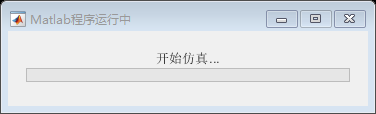

isuseParfeval = false;
h = waitbar(0, "开始仿真...", 'Name', 'Matlab程序运行中');

startTime = tic;

parHandleArray = parallel.FevalFuture.empty;
maxParallelTasks = 1; % 根据硬件条件调整任务数
taskIndexMap = containers.Map('KeyType', 'uint32', 'ValueType', 'any'); % 存储任务索引

一次读取一个仿真的参数，进行模拟

totalNum = nIter*modelNum;
energy = zeros(idNums, totalNum);
absorbance = zeros(idNums, totalNum);
detPath = zeros(size(ua,2), idNums, totalNum);
% ringphotonDensity = zeros(length(SDS), totalNum);
% ringphotonEnergy = zeros(length(SDS), totalNum);
numVoxels = zeros(length(SDS), totalNum);
detpSize = zeros(1, totalNum);

depthWritePath = sprintf("%s/%s", savedataPath, depthFilePath);
fluxWritePath = sprintf("%s/%s", savedataPath, fluxFilePath);
replayWritePath = sprintf("%s/%s",savedataPath,depthFilePath);

disp(mcxlab('version'))

v2024.6



第1次仿真
波长:999.9 nm  模型:1 


Launching MCXLAB - Monte Carlo eXtreme for MATLAB & GNU Octave ...
Running simulations for configuration #1 ...
mcx.respin=1;
mcx.unitinmm=0.01;
mcx.seed=1648335518;
mcx.nphoton=5e+06;
mcx.outputtype='flux';
mcx.issrcfrom0=1;
mcx.dim=[800 800 815];
mcx.mediabyte=4;
mcx.shapedata='{"Shapes":[{"Grid": {"Tag":0, "Size":[800,800,815]}},{"Box": {"Tag":1, "O": [0,0,0], "Size": [800,800, 40]}},{"Box": {"Tag":2, "O": [0,0, 40], "Size": [800,800, 20]}},{"Box": {"Tag":3, "O": [0,0, 60], "Size": [800,800, 2]}},{"Box": {"Tag":4, "O": [0,0, 62], "Size": [800,800, 5]}},{"Box": {"Tag":5, "O": [0,0, 67], "Size": [800,800, 10]}},{"Box": {"Tag":6, "O": [0,0, 77], "Size": [800,800, 8]}},{"Box": {"Tag":7, "O": [0,0, 85], "Size": [800,800, 20]}},{"Box": {"Tag":8, "O": [0,0, 105], "Size": [800,800, 20]}},{"Box": {"Tag":9, "O": [0,0, 125], "Size": [800,800, 20]}},{"Box": {"Tag":10, "O": [0,0, 145], "Size": [800,800, 20]}},{"Box": {"Tag":11, "O": [0,0, 165], "Size": [800,800, 20]}},{"Box": {"Tag":12, "O": [0,


第2次仿真
波长:1000 nm  模型:1 


Launching MCXLAB - Monte Carlo eXtreme for MATLAB & GNU Octave ...
Running simulations for configuration #1 ...
mcx.respin=1;
mcx.unitinmm=0.01;
mcx.seed=1648335518;
mcx.nphoton=5e+06;
mcx.outputtype='flux';
mcx.issrcfrom0=1;
mcx.dim=[800 800 815];
mcx.mediabyte=4;
mcx.shapedata='{"Shapes":[{"Grid": {"Tag":0, "Size":[800,800,815]}},{"Box": {"Tag":1, "O": [0,0,0], "Size": [800,800, 40]}},{"Box": {"Tag":2, "O": [0,0, 40], "Size": [800,800, 20]}},{"Box": {"Tag":3, "O": [0,0, 60], "Size": [800,800, 2]}},{"Box": {"Tag":4, "O": [0,0, 62], "Size": [800,800, 5]}},{"Box": {"Tag":5, "O": [0,0, 67], "Size": [800,800, 10]}},{"Box": {"Tag":6, "O": [0,0, 77], "Size": [800,800, 8]}},{"Box": {"Tag":7, "O": [0,0, 85], "Size": [800,800, 20]}},{"Box": {"Tag":8, "O": [0,0, 105], "Size": [800,800, 20]}},{"Box": {"Tag":9, "O": [0,0, 125], "Size": [800,800, 20]}},{"Box": {"Tag":10, "O": [0,0, 145], "Size": [800,800, 20]}},{"Box": {"Tag":11, "O": [0,0, 165], "Size": [800,800, 20]}},{"Box": {"Tag":12, "O": [0,

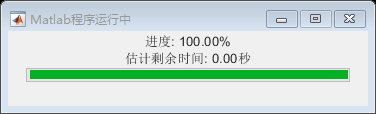

for j = 1:modelNum
    % 创建模型
    if isuseModelInExcel
        layers = modelData(j, :)./cfg.unitinmm;
        [cfg.shapes, cfg.vol] = makeSkinWithMask(cfg.vol, layers);
    end

    for i = 1:step:nIter*step
        index = i + (j - 1)*nIter;
        fprintf("\n第%d次仿真\n波长:%s nm  模型:%d \n", index, num2str(wavelength(i)), j);
        
        % 设置层的参数   [mua,mus,g,n]
        prop = [ua(index,:);us(index,:);g(index,:);n(index,:)]';
        cfg.prop = [0 0 1 1; prop];
        cfg.prop(1:size(cfg.prop,1), 1:2) = cfg.prop(1:size(cfg.prop,1), 1:2) / 10;  % cm-1 -> mm-1
    
        if isusebandwidth
            cfg.nphoton = nphotons(i);
        end
    
        % Simulation
        [flux, detp, ~, seeds] = mcxlab(cfg);
        
        try
            detpSize(index) = numel(detp.detid);
        catch 
            % 出现报错后继续运行下一次仿真
            errordlg(['波长: ' num2str(wavelength(i)) '模型' num2str(j) '仿真出错'])
            continue;
        end
        
        % 保存每次模拟的结果
        if issave
            % savejd('', f, 'filename', sprintf("%s/%d-f",savedataPath,excel_data.parameterwave(i)), 'compression', 'zlib');
            savejd('', detp, 'filename', sprintf("%s/%d-detp",savedataPath,opticalProperties.parameterwave(i)), 'compression', 'zlib');
        end
        
        % 根据开关变量决定使用 parfeval 还是直接获取结果
        if isuseParfeval
            if length(parHandleArray) < maxParallelTasks
                parHandle = parfeval(@exportMCX, 3, ...
                    cfg, detp, detectorType, absorbanceWritePath, ...
                    idNums, SDS, SDSWidth, responseWave, wavelength(i), ...
                    isusefakeSDS, isuseresponse, isAngle);
                parHandleArray(end+1) = parHandle;
                taskIndexMap(parHandle.ID) = index; % 记录任务的 index
            end
        else
            % 直接执行任务并获取结果
            [energy(:,index), absorbance(:,index), detPath(:,:,index)] = exportMCX(...
                cfg, detp, detectorType, absorbanceWritePath, ...
                idNums, SDS, SDSWidth, responseWave, wavelength(i), ...
                isusefakeSDS, isuseresponse, isAngle);
        end
        
        % 考虑导出Jacobian矩阵
        if isjacobian
            if strcmp(detectorType, 'single')
                exportJacobian(cfg, detp, seeds, gridX/2, ...
                    sprintf("%s/%g", savedataPath, wavelength(i)), ...
                    'outputtype' ,jacobianOutputType, ...
                    'isSlice', isSlice);
            else
                exportJacobian(cfg, detp, seeds, gridX/2, ...
                    sprintf("%s/%g", savedataPath, wavelength(i)), ...
                    'SDS', SDS, 'width', SDSWidth, ...
                    'outputtype' ,jacobianOutputType, ...
                    'isSlice', isSlice);
            end
        end

        % 考虑光子计数
        if isphotonnum
            if strcmp(detectorType, 'single')
                exportPhotonPath(cfg, detp, seeds, gridX/2, ...
                    sprintf("%s/%g", savedataPath, wavelength(i)), ...
                    'numWorkers', 4);
            else
                exportPhotonPath(cfg, detp, seeds, gridX/2, ...
                    sprintf("%s/%g", savedataPath, wavelength(i)), ...
                    'SDS', SDS, 'width', SDSWidth, 'numWorkers', 4);
            end
        end
        
        % 考虑导出穿透深度
        if isreplay
            if strcmp(detectorType, 'single')
                [photonMaximumDepth, photonMeanDepth, photonPPath] = exportDepth2(cfg, seeds, detp, replayThresh, ...
                    'isppath', isppath);
            else
                [photonMaximumDepth, photonMeanDepth, photonPPath] = exportDepth2(cfg, seeds, detp, replayThresh, ...
                    'SDS', SDS, 'width', SDSWidth, 'isppath', isppath);
            end

            writematrix(photonMeanDepth, depthWritePath,'WriteMode', 'append', 'Sheet', '加权穿透深度')
            writetable(photonMaximumDepth, depthWritePath,'WriteMode', 'append', 'Sheet', strcat('穿透深度-',string(ceil(i/step))))
            writetable(photonPPath, depthWritePath, 'WriteMode', 'append', 'Sheet', strcat('光程-',string(ceil(i/step))))
        end

         % 检查已完成的任务并获取结果（仅在使用 parfeval 时执行）
        if isuseParfeval
            while ~isempty(parHandleArray) && length(parHandleArray) >= maxParallelTasks
                completedIdx = fetchNext(parHandleArray);
                completedID = parHandleArray(completedIdx).ID; % 获取任务 ID
                currentIndex = taskIndexMap(completedID); % 获取任务对应的 index

                % 提取结果
                [energy(:,currentIndex), absorbance(:,currentIndex), detPath(:,:,currentIndex)] = ...
                    parHandleArray(completedIdx).OutputArguments{:};

                % 移除已完成的句柄和索引
                parHandleArray(completedIdx) = [];
                remove(taskIndexMap, completedID);
            end
        end        
    
        elapsedTime = toc(startTime);
        estimatedTotalTime = (elapsedTime / index) * nIter * modelNum; % 估算总时间
        remainingTime = estimatedTotalTime - elapsedTime; % 剩余时间
    
        % 更新 waitbar 显示
        waitbar( index/nIter/modelNum, h,...
            sprintf('运行波长: %d\n运行模型: %d\n进度: %.2f%%\n估计剩余时间: %.2f秒',...
            wavelength(i), j, index / nIter/modelNum * 100, remainingTime));
    end
end

确保最后未完成任务也处理完

while ~isempty(parHandleArray)
    completedIdx = fetchNext(parHandleArray);
    completedID = parHandleArray(completedIdx).ID;
    currentIndex = taskIndexMap(completedID);

    [energy(:,currentIndex), absorbance(:,currentIndex), detPath(:,:,currentIndex)] = ...
        parHandleArray(completedIdx).OutputArguments{:};

    parHandleArray(completedIdx) = [];
    remove(taskIndexMap, completedID);
end

### 计算光密度

energy = energy(energy(:,1)~=0,:);
S = pi*((SDS + SDSWidth/2).^2 - (SDS - SDSWidth/2).^2);
density = energy ./ S' / cfg.nphoton / cfg.respin;

writematrix(density', absorbanceWritePath, 'Sheet','光密度');
writematrix(detpSize, absorbanceWritePath, 'Sheet','检测器检测光子数');

if strcmp(detectorType, "overlap")
    writematrix(energy, absorbanceWritePath, 'Sheet', '光能量');
end

### 绘制图像

启动图像绘制后，会自动将光密度的光谱和衰减曲线绘制

if isplot
    wavelength = [1050, 1219, 1314, 1409, 1550, 1609];
    figure , 
    tiledlayout(3,1,'TileSpacing', 'tight')
    
    % 绘制光密度
    nexttile, plot(SDS, density, '-o', 'LineWidth', 1), legend(num2str(wavelength'))
    xlabel('SDS (mm)'), ylabel('photon density'), title('photon density')
    
    nexttile, plot(wavelength, density', '-o', 'LineWidth', 1), legend(num2str(SDS'))
    xlabel('wavelength (nm)'), ylabel('photon density'), title('spectrum')
    nexttile, mcxplotshapes(cfg.shapes, [gridX, gridY, gridZ]);
end

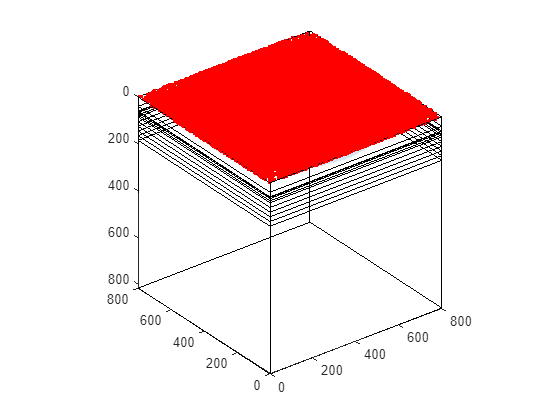

figure, 
mcxplotshapes(cfg.shapes);
hold on 
set(gca, 'ZDir', 'reverse')
plotmesh(detp.p,'r.')
hold off

### 保存模拟设置

将模拟中的设置保存为pdf，存在一些问题，可能需要在运行后摁ctrl + s

% matlab.internal.liveeditor.openAndConvert ('MCX_Skin7.mlx', [char(savedataPath) '/log.pdf'], 'HideCode', false);
export('MCX_Skin7.mlx', [char(savedataPath) '/log.pdf'], 'HideCode', false);